# Esercizio 1

## Dato la seguente Fdt $G(s)=\frac{10}{s(s+2)(s+10)}$ progettare un regolatore standard digitale tale:

- **Errore nullo rispetto ad un riferimento a gradino.**

- **Sovra-elongazione percentuale massima pari al 10% e tempo di assestamento minore di 2sec**

Passi da svolgere:

        (a) Implementare in Simulink il sistema;

        (b) Tarare i parametri per regolatori standard del tipo PD, PI o PID, ipotizza di non conoscere il modello dell'dell’impianto;

        (c) Discretizzare i regolatori ottenuti dopo opportuna scelta del passo di campionamento.

Sappiamo :

- Il controllo P è usato quando un errore al gradino non nullo è tollerabile oppure quando il processo ha un polo nell’origine 

- Il controllo PI è usato quando l’annullamento dell’errore a regime è importante 

- Il controllo PD è usato per aumentare la banda di controllo nei processi lenti o per attenuare le oscillazioni nelle risposte

- Il controllo PID completo viene usato quando banda di controllo elevate e errori a regimi nulli sono entrambi importanti.

Dalle specifiche di progetto notiamo come nel nostro caso sia utile il PID.

Definiamo i parametri da tarare

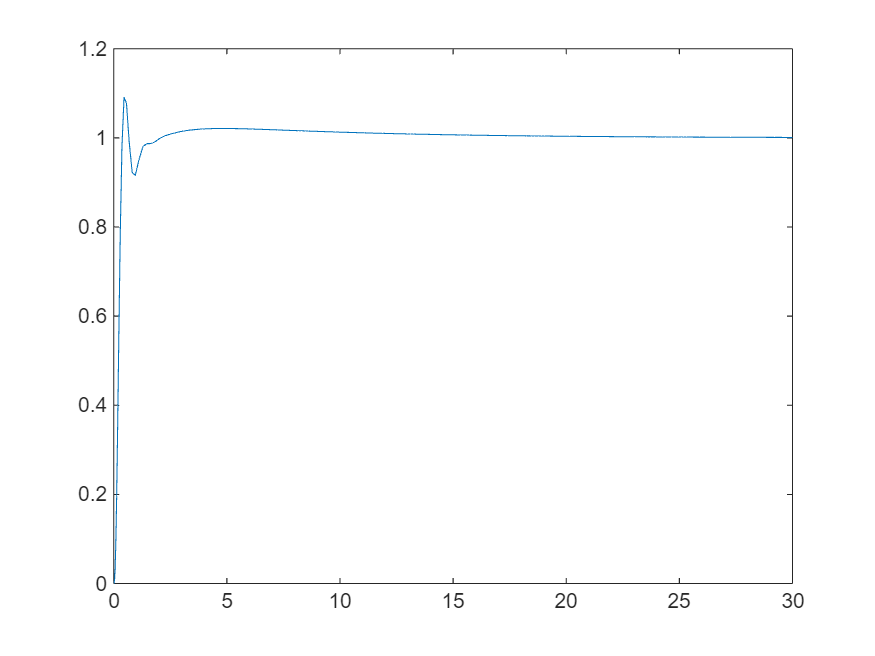

%metodo ad anello chiuso
%metodo ziegler-nichols ad anello chiuso:
Kc=24; %Kc CRITICO è circa 24,con componenti integrative e derivative nulle
Tc=1.377; %con Kc il TEMPO TRA LE OSCILLAZIONI è circa 1.3 s
KP=0.6*Kc;
TI=0.5*Tc;
TD=0.125*Tc;

plot(out.Time,out.Y)

stepinfo(out.Y,'SettlingTimeThreshold',0.05)

ans = struct with fields:
         RiseTime: 4.5100
    TransientTime: 23.0530
     SettlingTime: 23.0530
      SettlingMin: 0.9160
      SettlingMax: 1.0916
        Overshoot: 9.0490
       Undershoot: 0
             Peak: 1.0916
         PeakTime: 18




%metodi ad anello aperto

% 1 metodo della curva di processo ad anello aperto:
% 2 metodo di approssimazione delle aree:
% 3 metodo ziegler-nichols ad anello aperto: